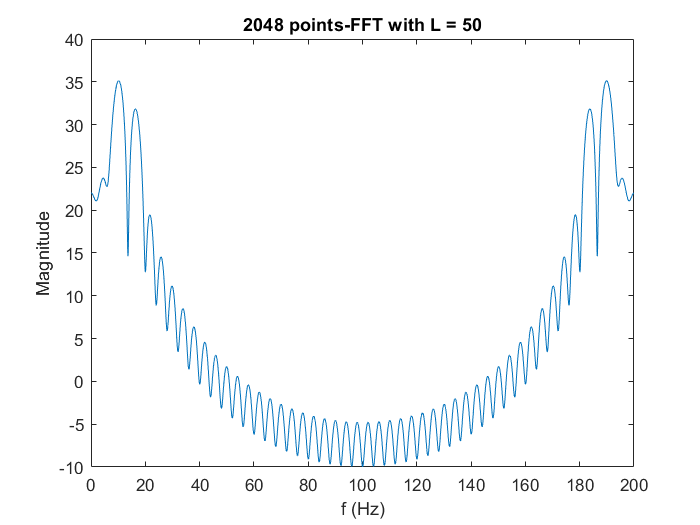

clc,clear,close all
f1 = 50;f2 = 60;f3 = 80;ts = 1/1000;fs = 1000;
n = 0:49;L = 50;
x = 2*sin(2*pi*f1*n*ts) + sin(2*pi*f2*n*ts) + 1.5*sin(2*pi*f3*n*ts);
X = fft(x,2048);

figure
plot(linspace(0,200,2048),20*log10(abs(X))) 
xlabel('f (Hz)')
ylabel('Magnitude')
title("2048 points-FFT with L = 50")

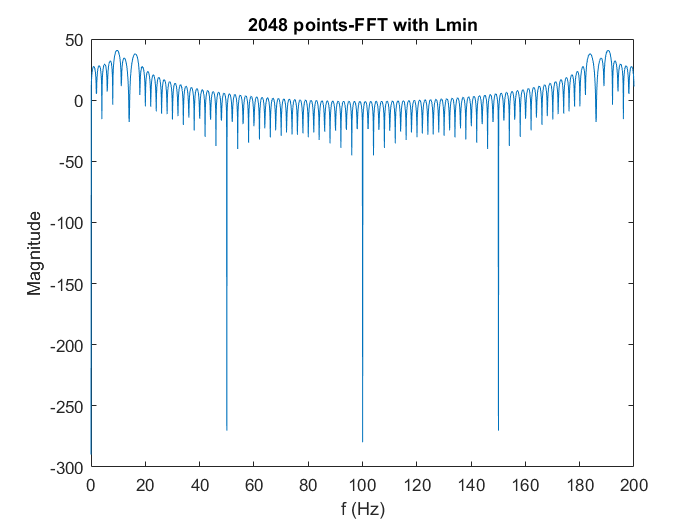

fmin = 10;
lmin = fs/fmin;
n=0:lmin-1;
x = 2*sin(2*pi*f1*n*ts) + sin(2*pi*f2*n*ts) + 1.5*sin(2*pi*f3*n*ts);
X = fft(x,2048);

figure
plot(linspace(0,200,2048),20*log10(abs(X))) 
xlabel('f (Hz)')
ylabel('Magnitude')
title("2048 points-FFT with Lmin")

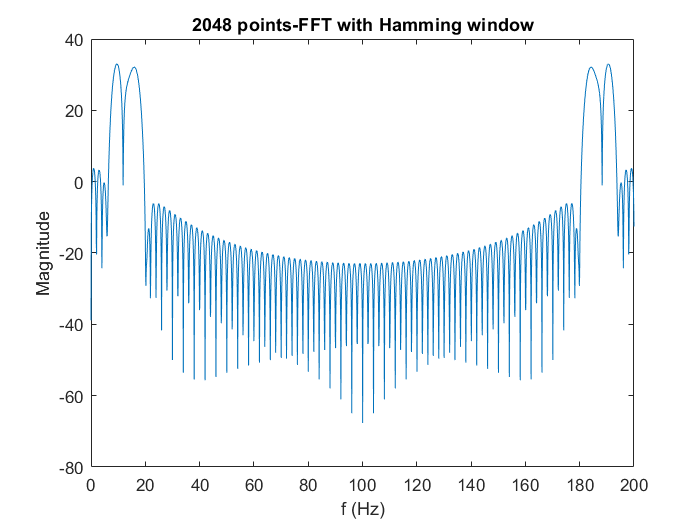


w = 0.54 - 0.46*cos(2*pi*n/(lmin - 1));
x_new = w.*x;
X_new = fft(x_new,2048);
figure
plot(linspace(0,200,2048),20*log10(abs(X_new))) 
xlabel('f (Hz)')
ylabel('Magnitude')
title("2048 points-FFT with Hamming window")